# Ball Segment All Frame Using apps function

## Read video frames from the ball.avi file.

clc;clear;close all;
videoFReader = vision.VideoFileReader('ball.avi',...
'VideoOutputDataType','double');

## Play the video file using the video player

Retrieve the screen size in pixels

r = groot;
scrPos = r.ScreenSize;

Size/position is always a 4-elementor: [x0 y0 dx dy]

dx = scrPos(3); dy = scrPos(4);
videoPlayer = vision.VideoPlayer('Position',[dx/8, dy/8, dx*(3/4), dy*(3/4)]);

 Create a AlphaBlender object to highlight the detected object in the original video frame.

alphaBlender = vision.AlphaBlender;
alphaBlender.Operation = 'Highlight selected pixels';

While Loop

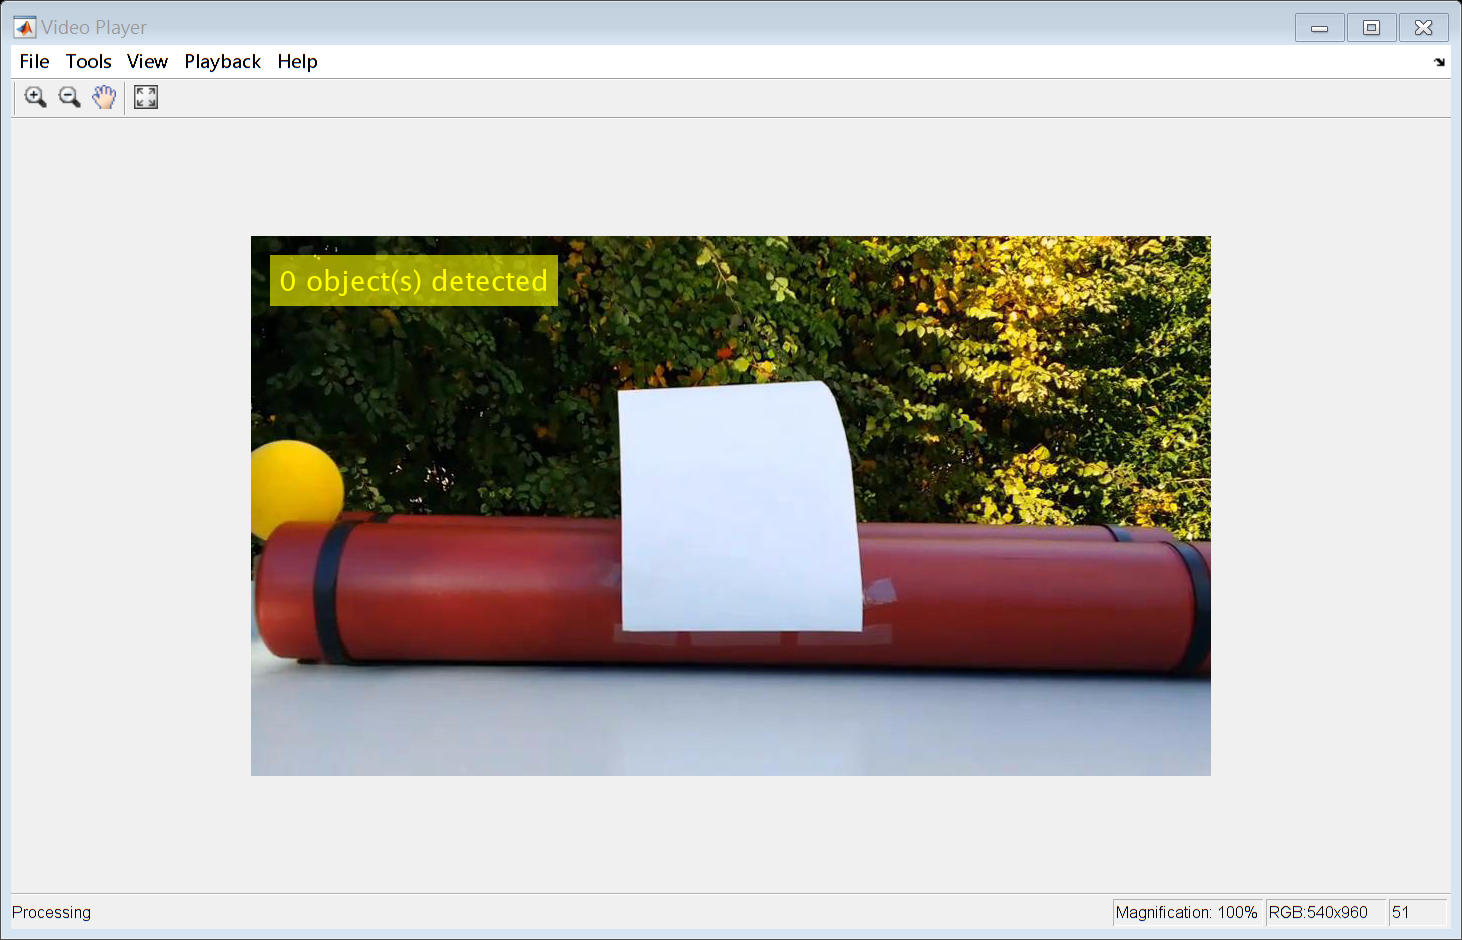

while ~isDone(videoFReader)
    
    videoFrame = videoFReader();
    
    [BW,maskedRGBImage] = createMask(videoFrame);
    [BW2,maskedImage] = segmentImage(videoFrame,BW);
    [BW_out,properties] = filterRegions(BW2);
    
    props = regionprops('table',BW_out,'Centroid','MajorAxisLength');
    videoFrame = alphaBlender(videoFrame, BW_out);
    
    %%
    numObj = length(props.MajorAxisLength);
    str = [num2str(numObj),' object(s) detected'];
    videoFrame = insertText(videoFrame,[20 20], str,...
        'textColor',[1 1 0],'FontSize',28);
    
    % Draw a circle around the detected objects
    videoFrame = insertShape(videoFrame, 'Circle', ...
        [props.Centroid,props.MajorAxisLength/2],'LineWidth',5) ;
    
    videoPlayer(videoFrame);
end